load("total_biomass.txt")
h=figure('Units','inches','Position',[0 0 3.25 2.5])

h =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 3.2500 2.5000]
       Units: 'inches'

  Show all properties


plot(0.05*total_biomass(1:5001,1)/24,total_biomass(1:5001,2),'LineWidth',2)
xlim([0,11])
ylim([0,2.2e-3])
xlabel('Time [days]')
ylabel('Total biomass [g]','FontSize',10)
ax=gca;
ax.FontSize=10

ax =   Axes with properties:

             XLim: [0 11]
             YLim: [0 0.0022]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1394 0.1611 0.7656 0.7572]
            Units: 'normalized'

  Show all properties


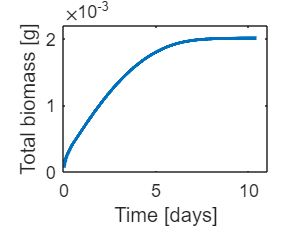

hold on 

media_glc_edge
%h=figure('Units','inches','Position',[0 0 1.25 0.9])
glucose(1:51)=0.0;
for t=1:51
    varname=genvarname(['media_' int2str((t-1)*100)]);
    glucose(t)=glucose(t)+eval(varname)/1e-4;
end

yyaxis right
f=plot(0.05*[0:100:5000]/24,glucose(:),'LineWidth',2)

f =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.2083 0.4167 0.6250 0.8333 1.0417 1.2500 1.4583 1.6667 1.8750 2.0833 2.2917 2.5000 2.7083 2.9167 3.1250 3.3333 3.5417 3.7500 3.9583 4.1667 4.3750 4.5833 4.7917 5 5.2083 5.4167 5.6250 5.8333 6.0417 6.2500 6.4583 6.6667 6.8750 … ]
              YData: [0.0047 0.0047 0.0047 0.0046 0.0044 0.0043 0.0041 0.0039 0.0038 0.0036 0.0034 0.0033 0.0031 0.0029 0.0028 0.0026 0.0025 0.0024 0.0022 0.0021 0.0020 0.0019 0.0017 0.0016 0.0015 0.0014 0.0014 0.0013 0.0012 0.0011 0.0010 9.7628e-04 … ]

  Show all prope

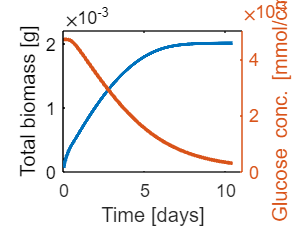

ax =   Axes with properties:

    YAxisLocation: 'right'
            YAxis: [2×1 NumericRuler]
             YLim: [0 0.0050]
             XLim: [0 11]
           XScale: 'linear'
           YScale: 'linear'
         Position: [0.1394 0.1611 0.7408 0.7406]
            Units: 'normalized'

  Show all properties


xlim([0,11])
xlabel('Time [days]','FontSize',10)
ylabel('Glucose conc. [mmol/cm^2]','FontSize',10)
ylim([0 5e-3])
%xticklabels(gcf,'FontSize',10)
ax=gca;
ax.FontSize=10

exportgraphics(gcf,"total_biomass_glucose.png",'Resolution', 1200)

%saveas(gcf,'total_biomass_glucose.png','Resolution', 1200)